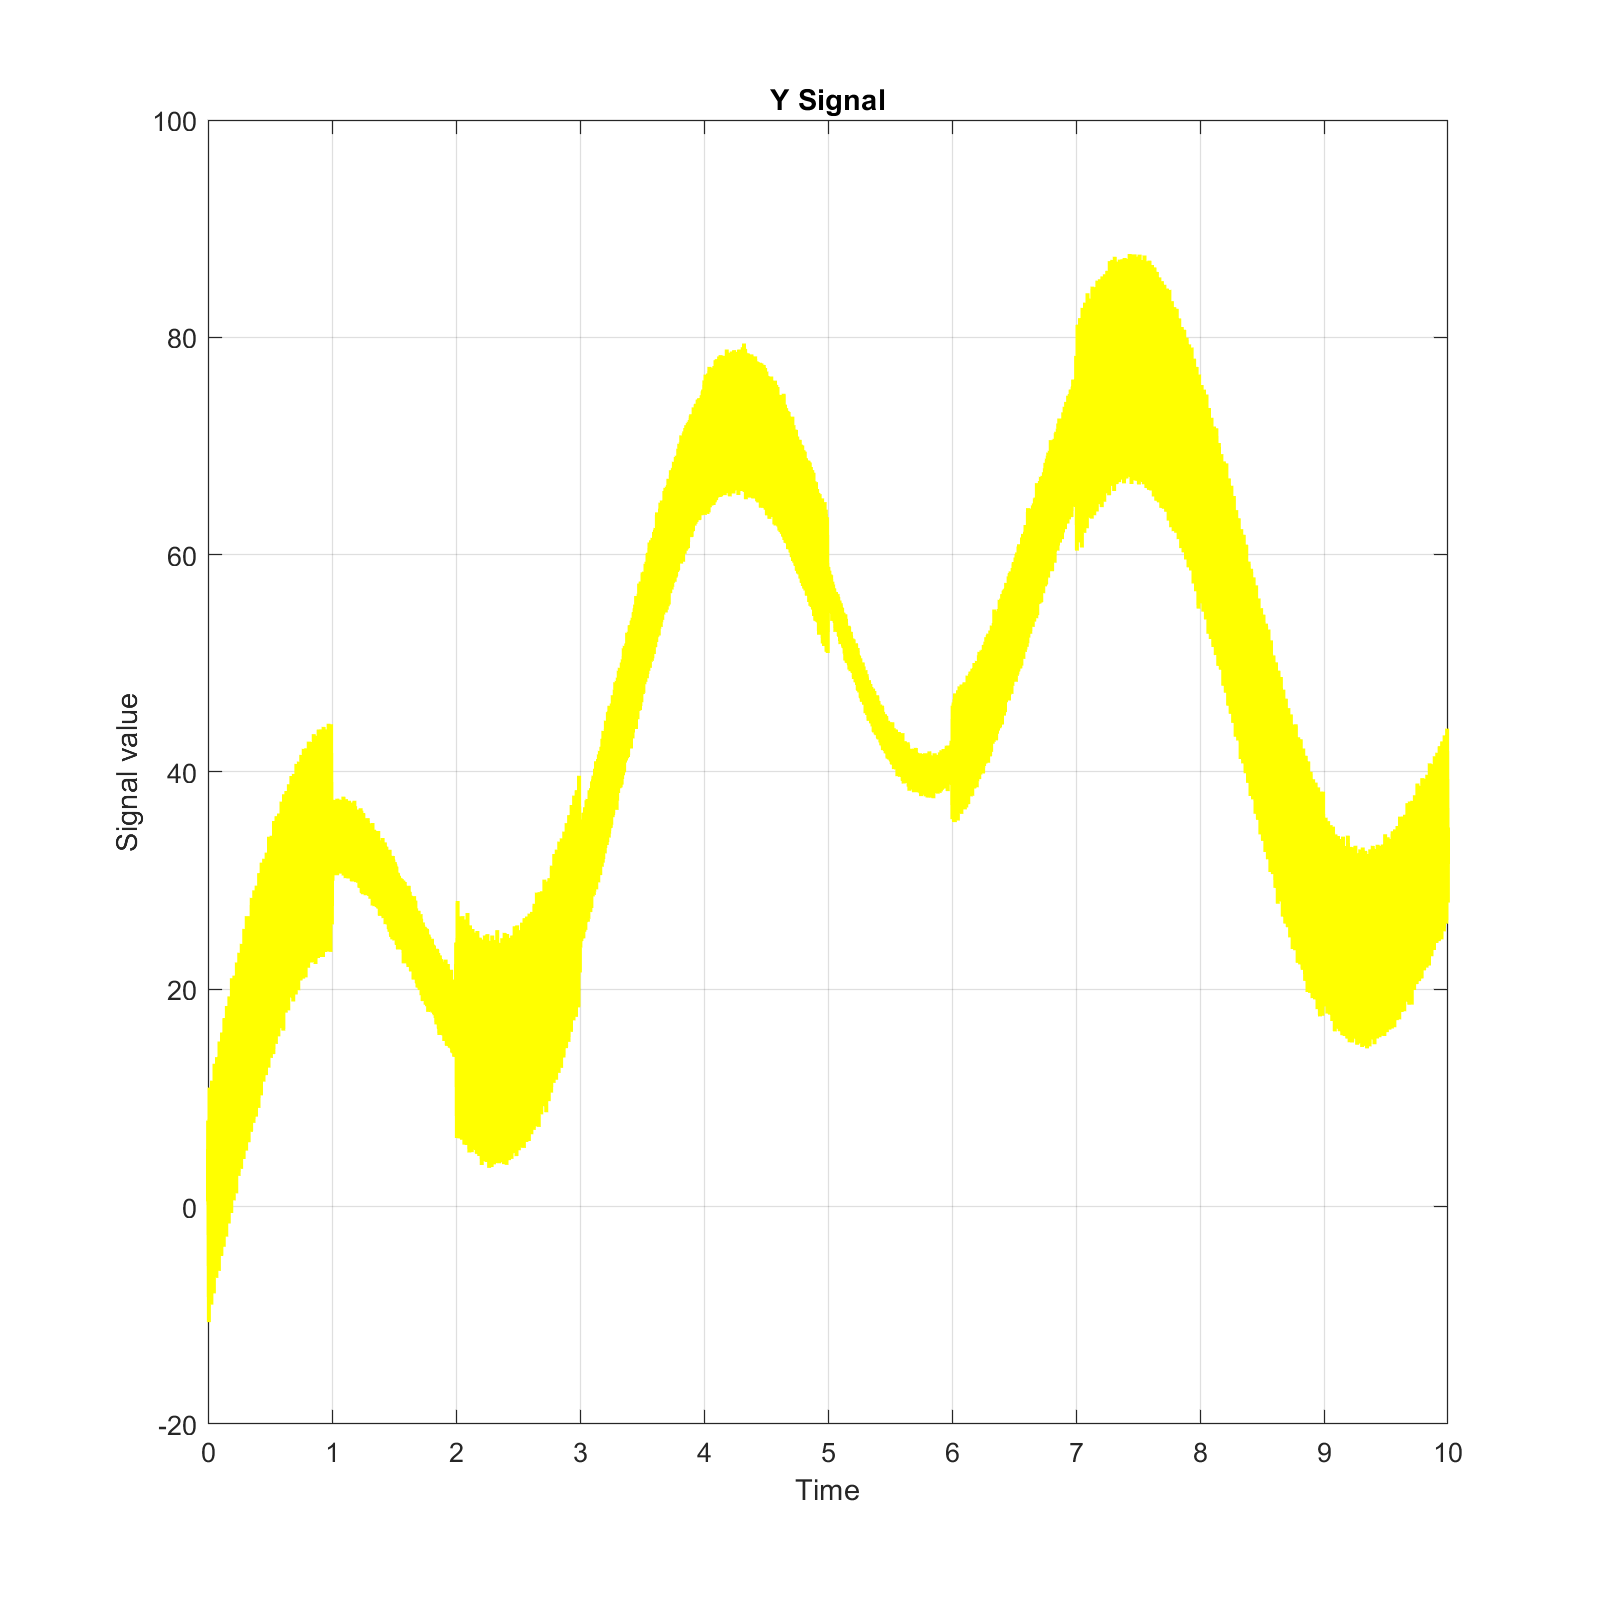

Y = HW2_sig(810199497);
t = linspace(0, 10, numel(Y));

figure('Name', 'Y Signal', 'Position', [100, 100, 800, 800]);

plot(t, Y, 'y', 'LineWidth', 1.5); 
grid on;
xlabel('Time');
ylabel('Signal value');
title('Y Signal'); 

s = tf('s');
f = 6

f = 6

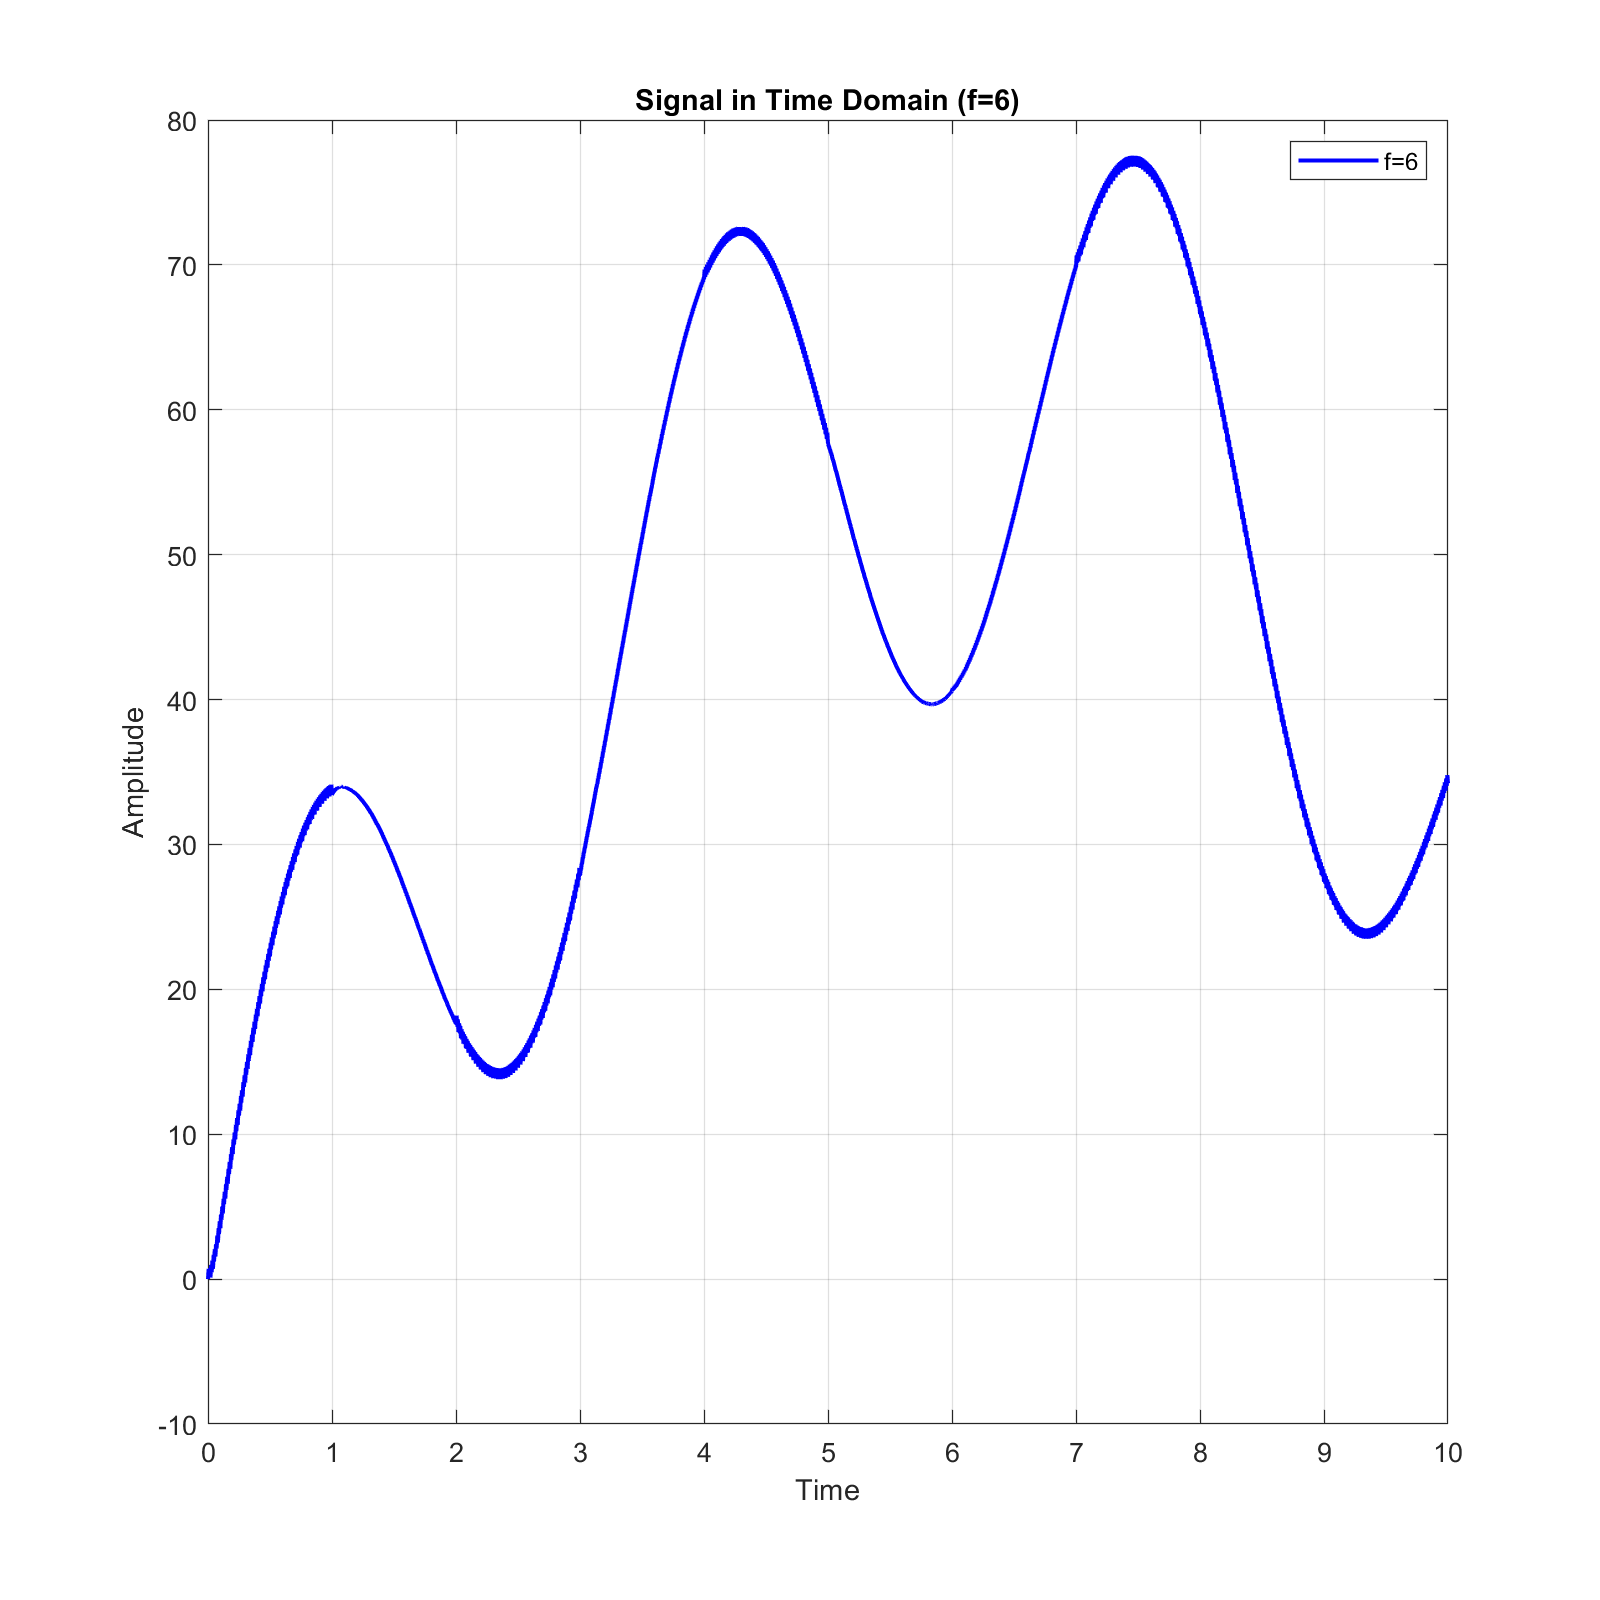


T = 1 / (2 * pi * f);
G = 1 / (T * s + 1);

Y_laplace = lsim(G, Y, t);
    

plot(t, Y_laplace, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time');
ylabel('Amplitude');
title(['Signal in Time Domain (f=', num2str(f), ')']);
legend(['f=', num2str(f)]);

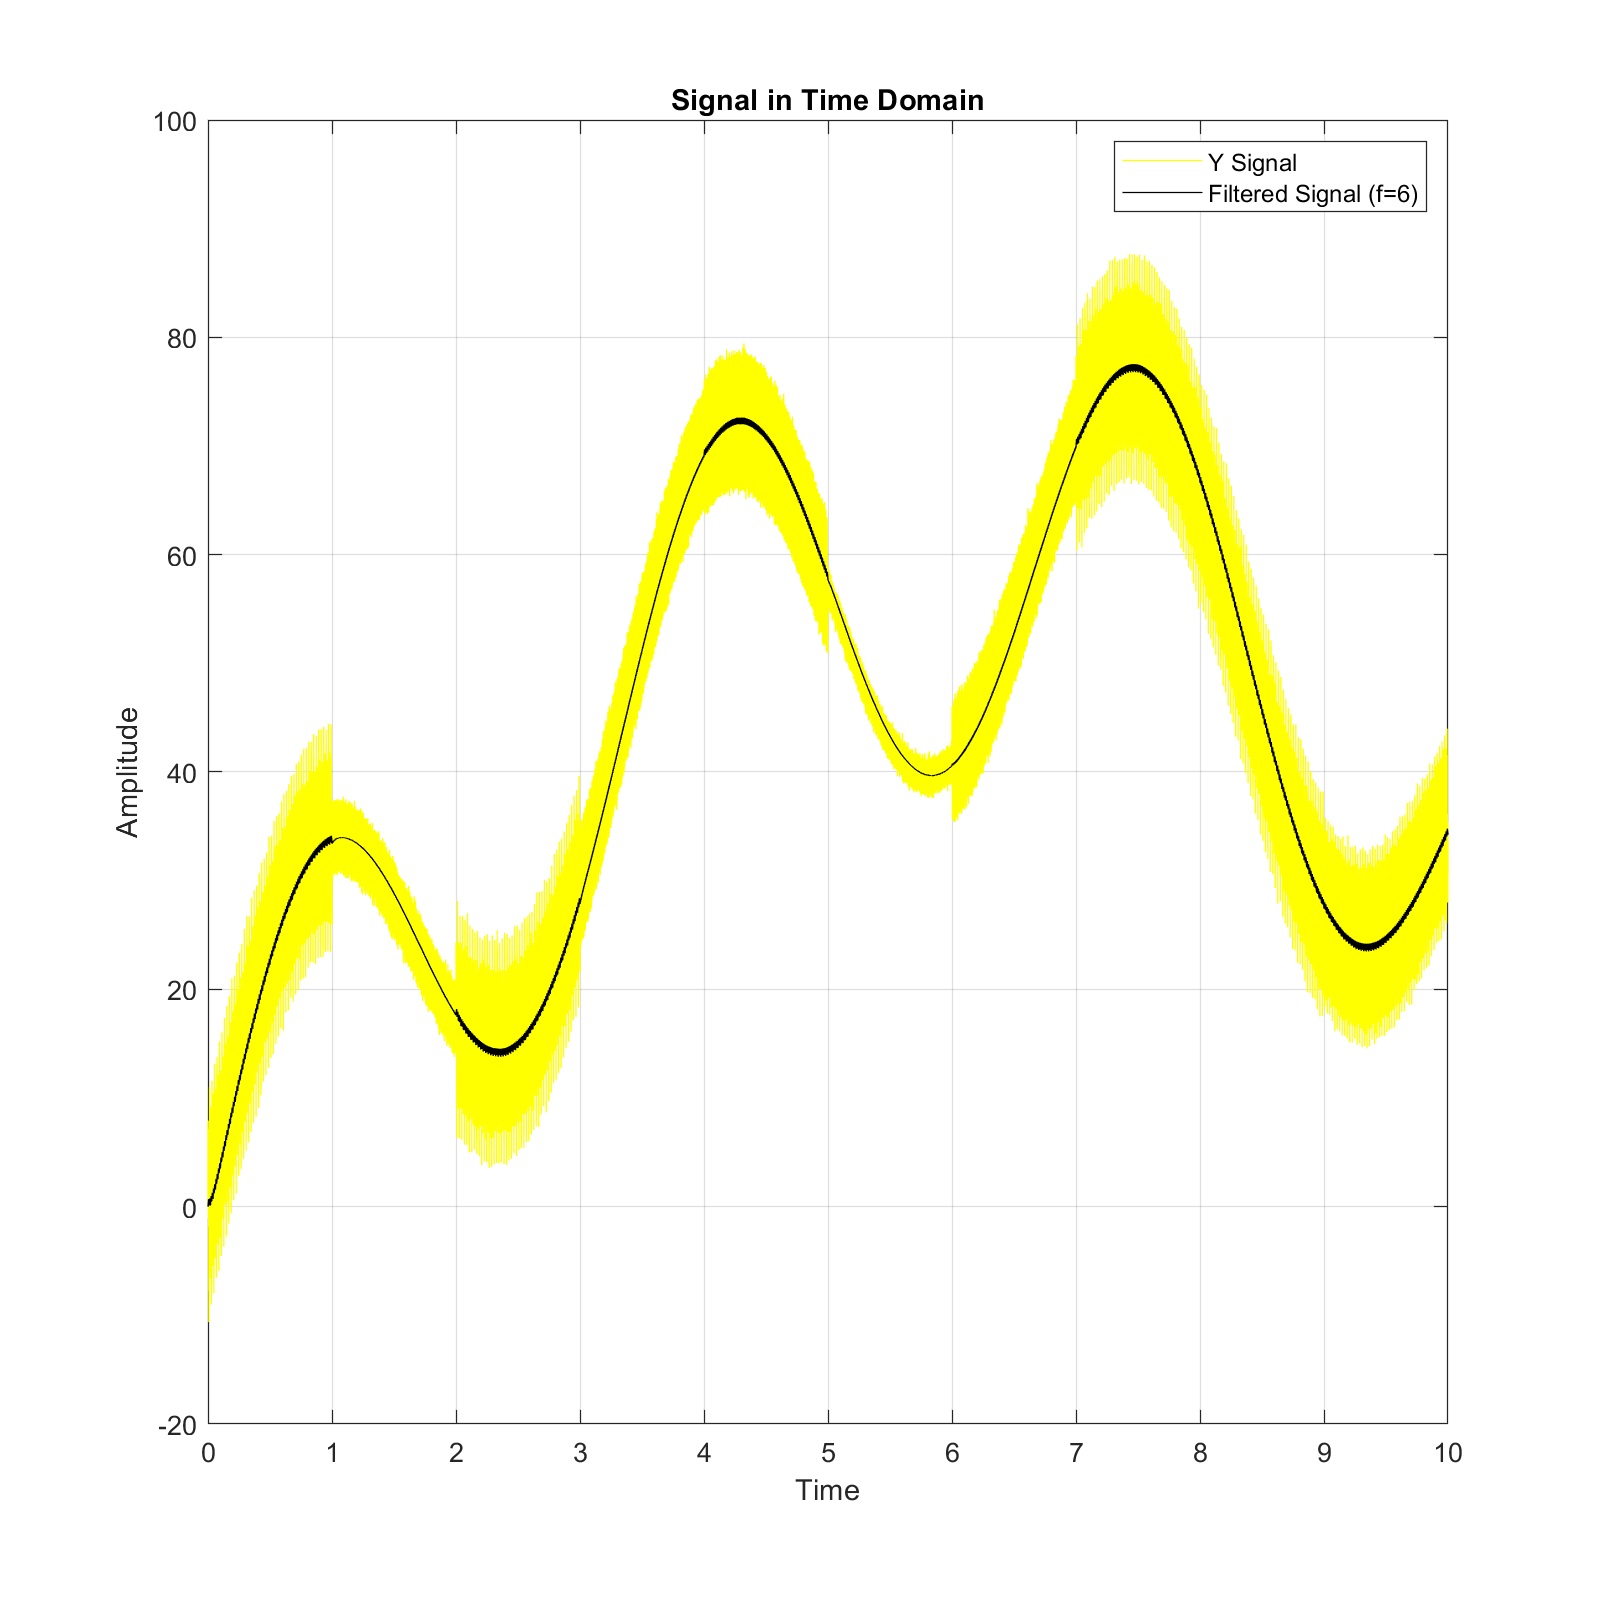


 T = 1 / (2 * pi * f);
 G = 1 / (T * s + 1);

 Y_laplace = lsim(G, Y, t);
    
 plot(t, Y, 'y');
 hold on;
 plot(t, Y_laplace,'k');
 hold off;
 grid on;
 xlabel('Time');
 ylabel('Amplitude');
 title('Signal in Time Domain');
 legend('Y Signal', ['Filtered Signal (f=', num2str(f), ')']);

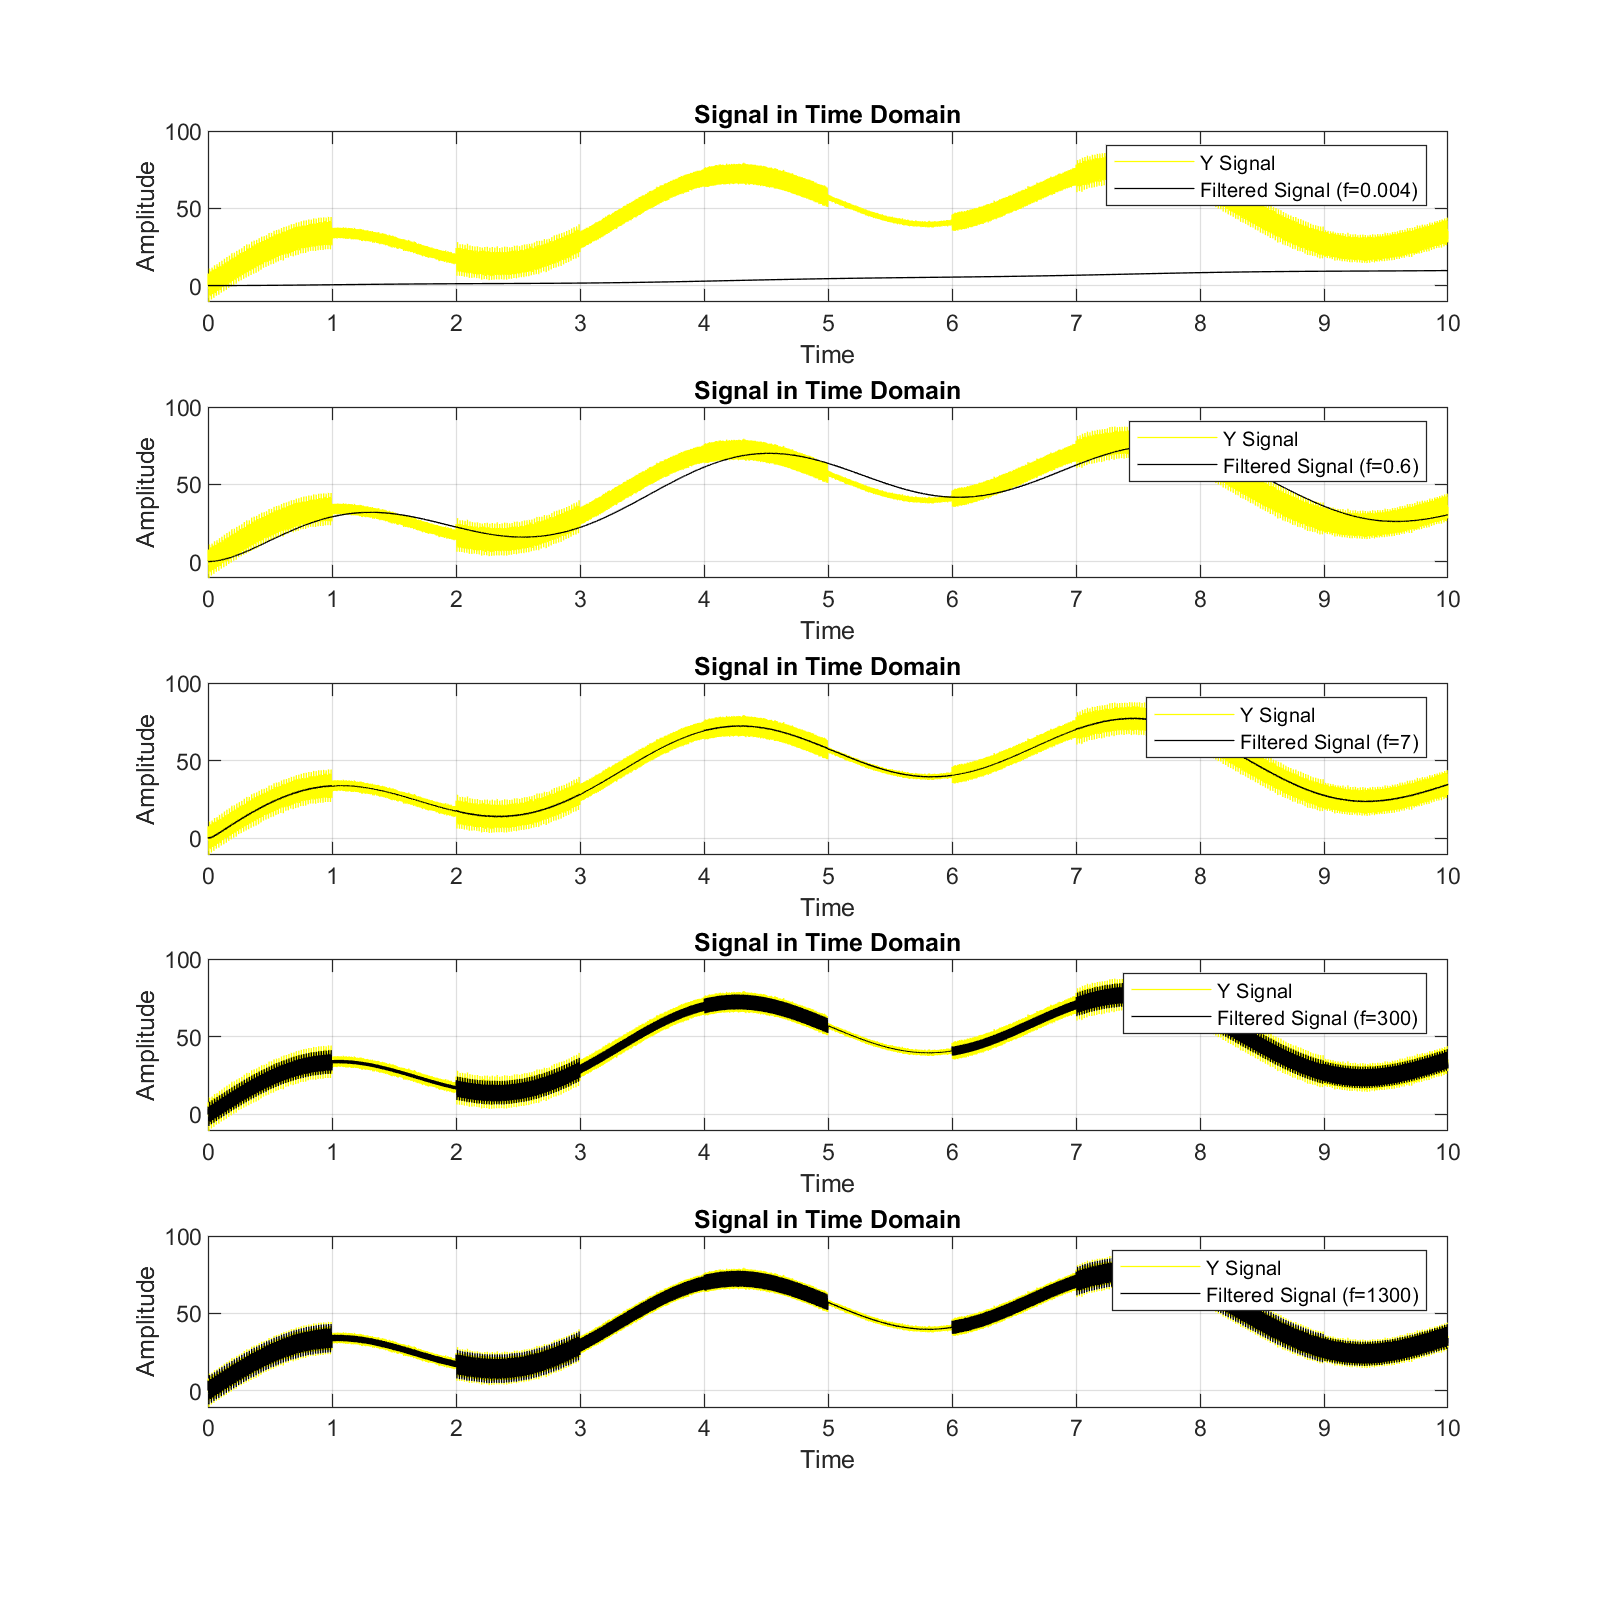

fi = [0.004,0.6,7,300,1300];
num_f = numel(fi);

for i = 1:num_f
    f = fi(i);
    T = 1 / (2 * pi * f);
    G = 1 / (T * s + 1);

    Y_laplace = lsim(G, Y, t);
    
    subplot(num_f, 1, i);
    plot(t, Y, 'y');
    hold on;
    plot(t, Y_laplace,'k');
    hold off;
    grid on;
    xlabel('Time');
    ylabel('Amplitude');
    title('Signal in Time Domain');
    legend('Y Signal', ['Filtered Signal (f=', num2str(f), ')']);
end

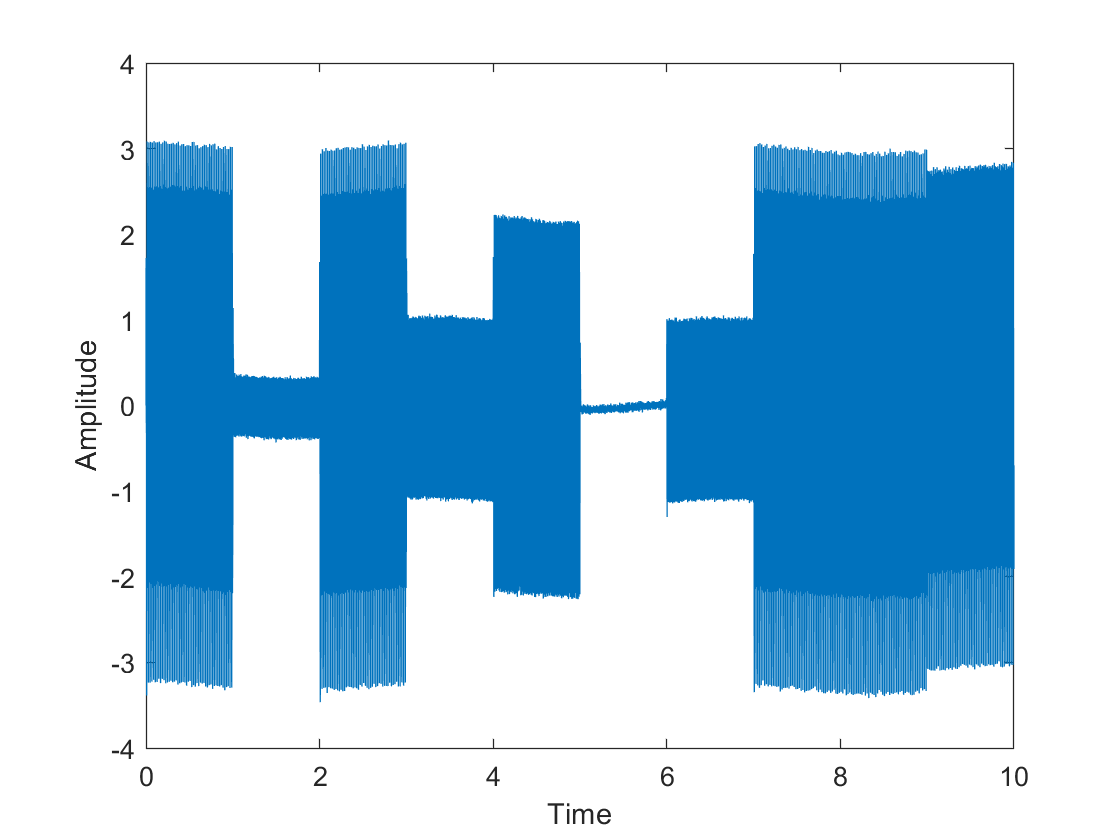

s = tf('s');
f1 = 85;
f2 = 110;
RC1 = 1 / (2 * pi * f1);
RC2 = 1 / (2 * pi * f2);

G = (RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1));

figure;
Y_N = lsim(G, Y, t);
plot(t, Y_N);
xlabel('Time');
ylabel('Amplitude');

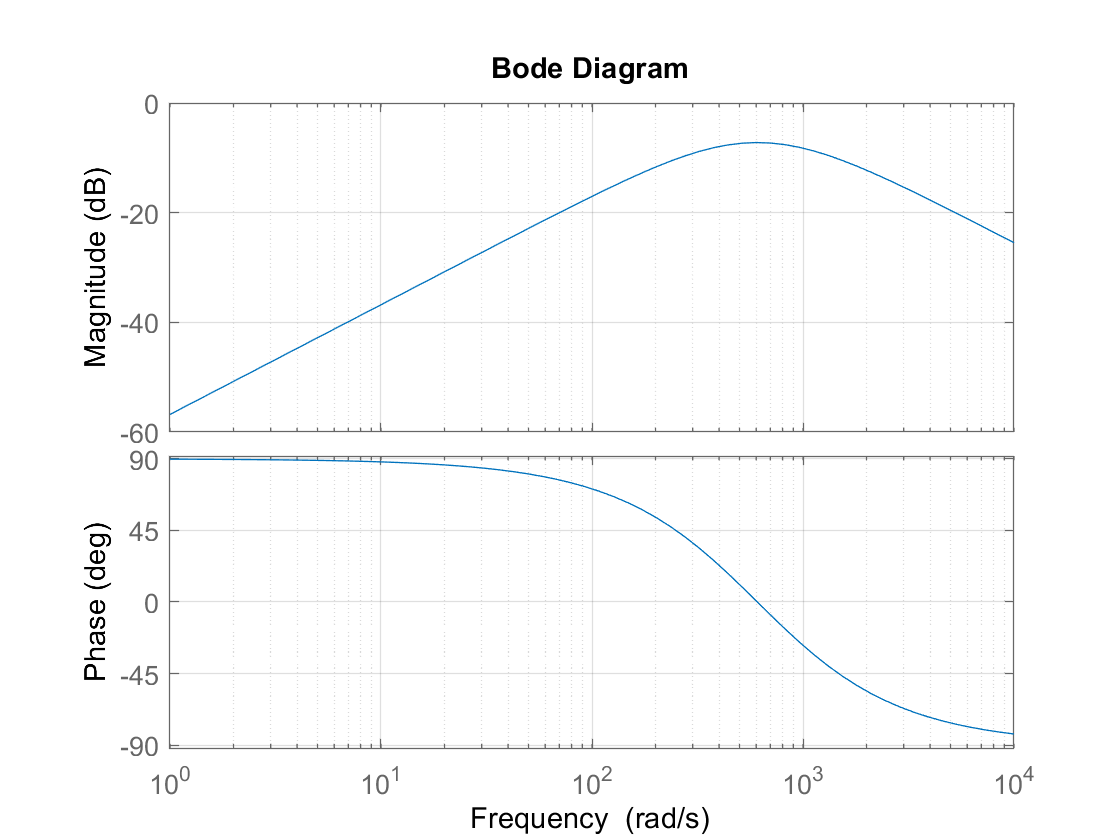

figure;
bode(G, {1, 10000}); 
grid on;

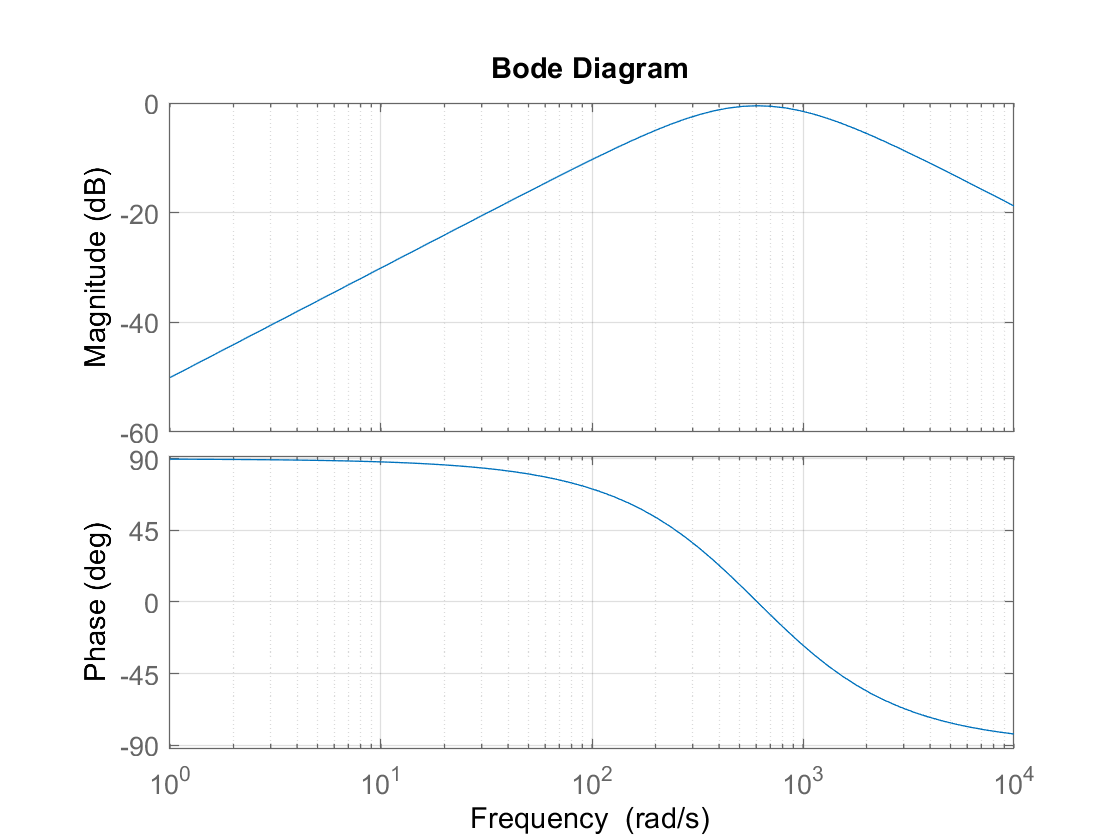

G = (2.1652 * RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1));
figure
bode(G, {1, 10000}); 
grid on

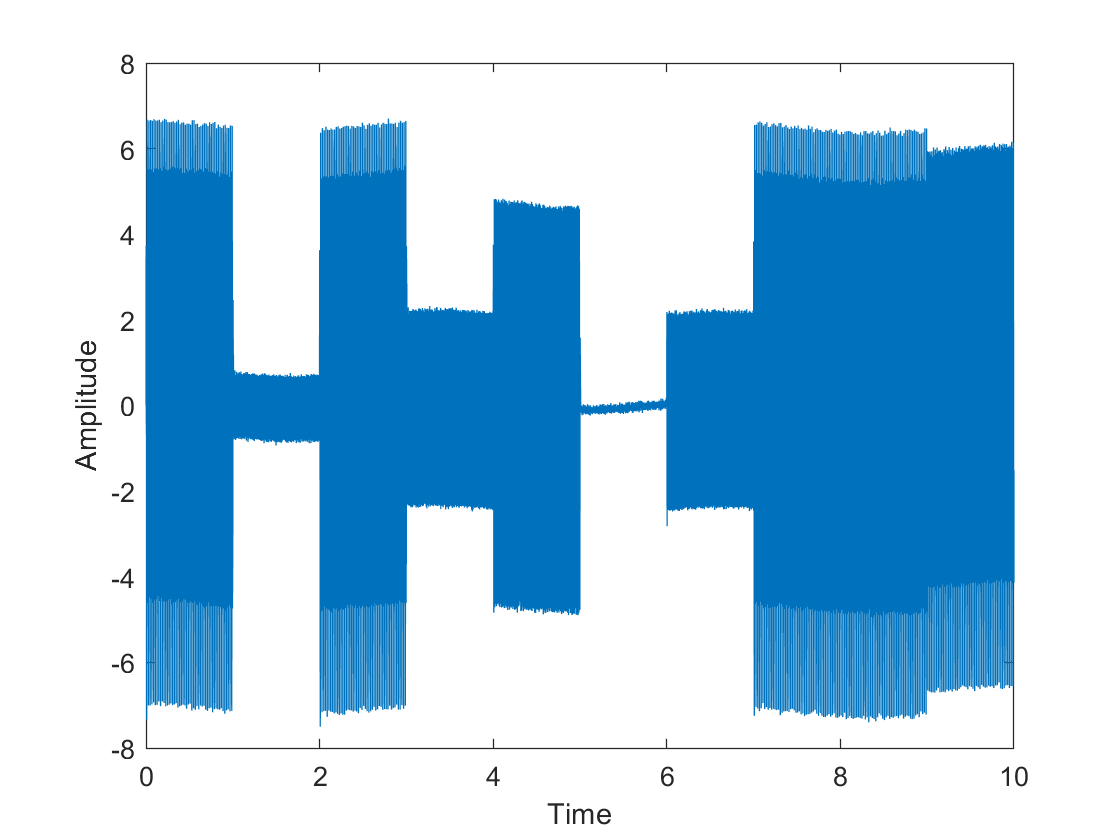

Y_NN = lsim(G, Y, t);

plot(t, Y_NN); 
xlabel('Time');
ylabel('Amplitude');

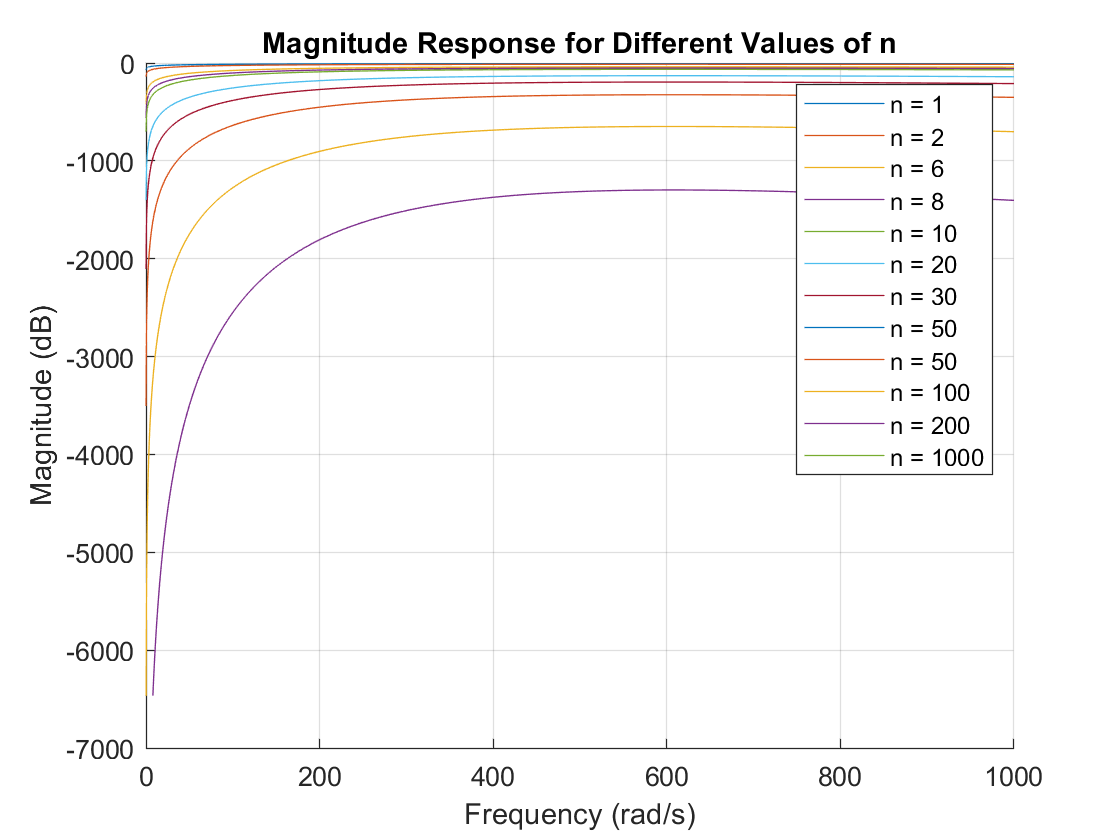

% Define parameters
n_values = [1, 2, 6, 8, 10, 20, 30, 50, 50, 100, 200, 1000];
f1 = 85;
f2 = 110;
RC1 = 1 / (2 * pi * f1);
RC2 = 1 / (2 * pi * f2);

% Create a figure
figure;
hold on;
grid on;
title('Magnitude Response for Different Values of n');

% Plot the magnitude response for each value of n
for i = 1:numel(n_values)
    s = logspace(-1, 3, 1000);  % Frequency range (logarithmic scale)
    G = (2.1652 * (RC2 * s) ./ ((RC1 * s + 1) .* (RC2 * s + 1))).^n_values(i);
    semilogx(s, 20 * log10(abs(G)), 'DisplayName', ['n = ' num2str(n_values(i))]);
end

% Add legend and labels
legend();
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
hold off;

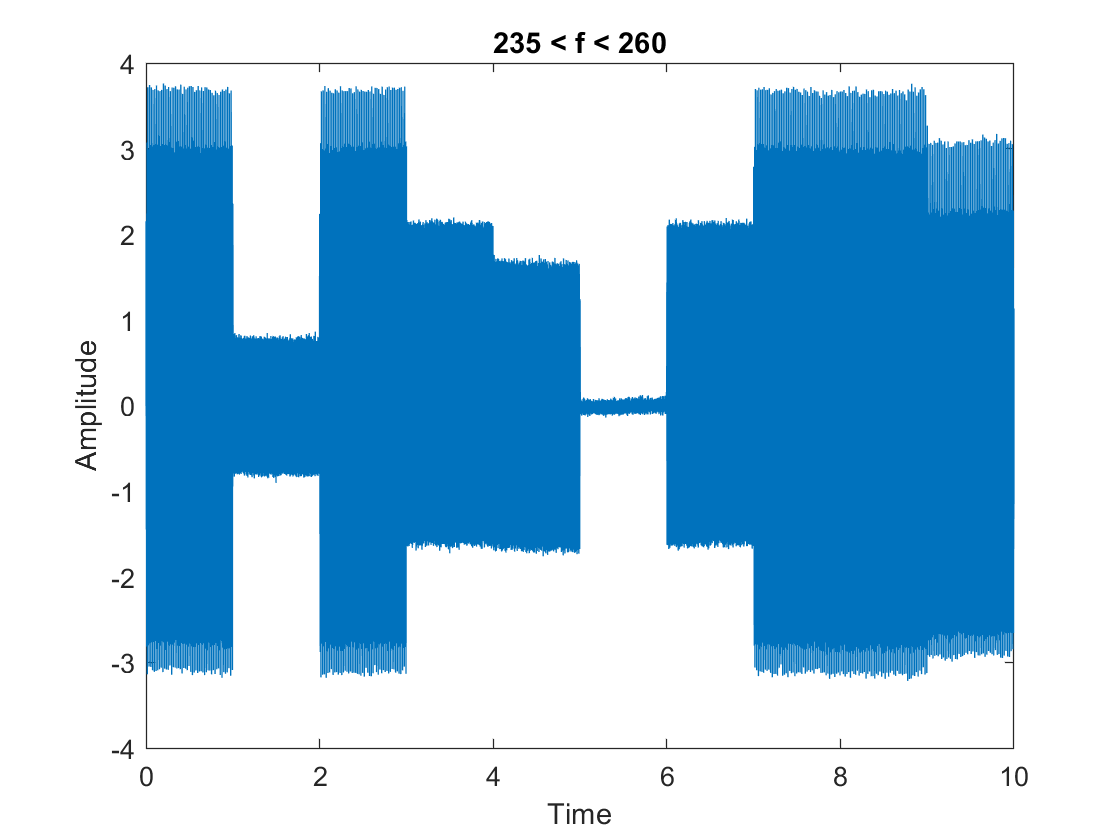

s = tf('s');
f1 = 235;
f2 = 260;
RC1 = 1 / (2 * pi * f1);
RC2 = 1 / (2 * pi * f2);

G = (RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1));

figure;
Y_N = lsim(G, Y, t);
plot(t, Y_N);
xlabel('Time');
ylabel('Amplitude');
title('235 < f < 260');

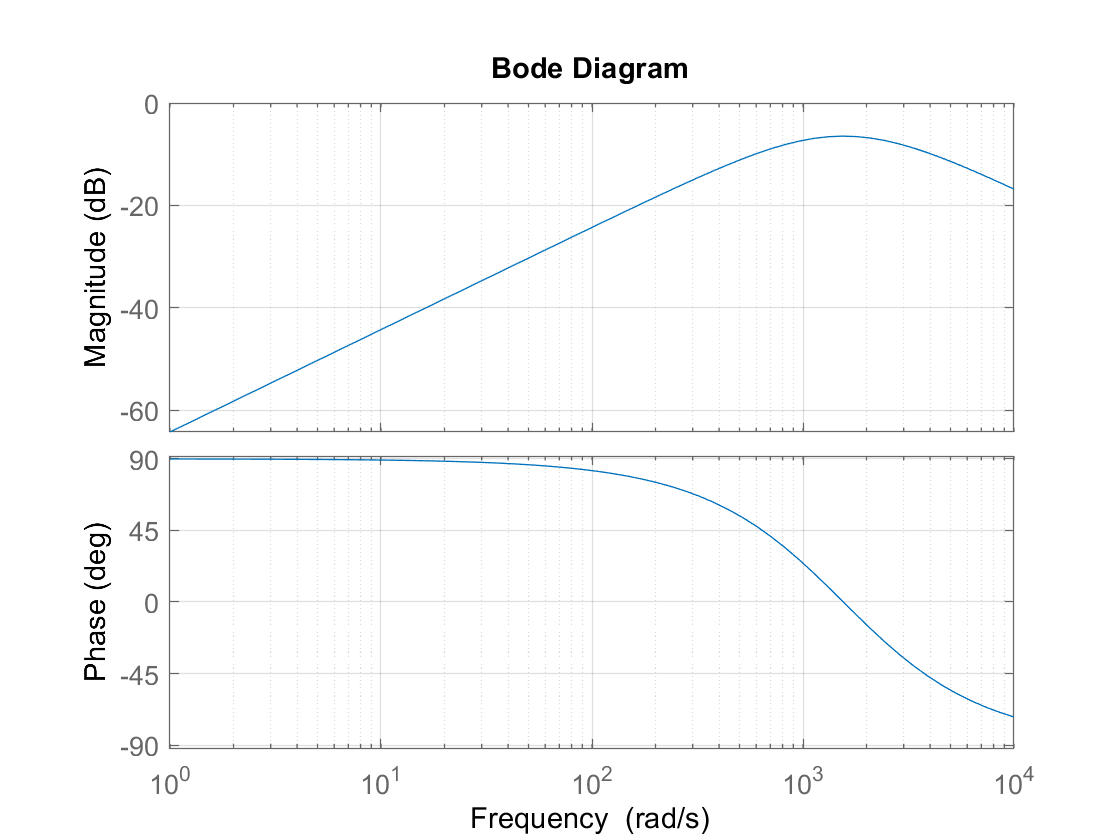

figure;
bode(G, {1, 10000}); 
grid on;

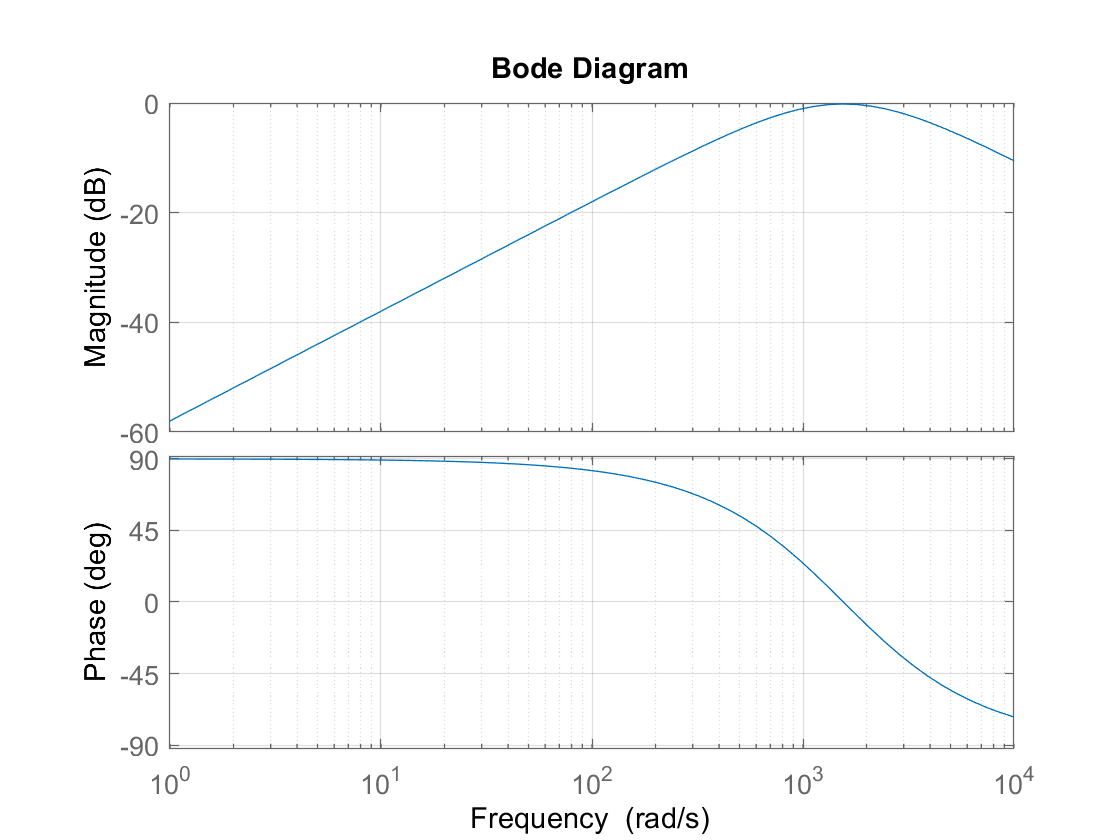

G = (2.063 * RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1));
figure
bode(G, {1, 10000}); 
grid on

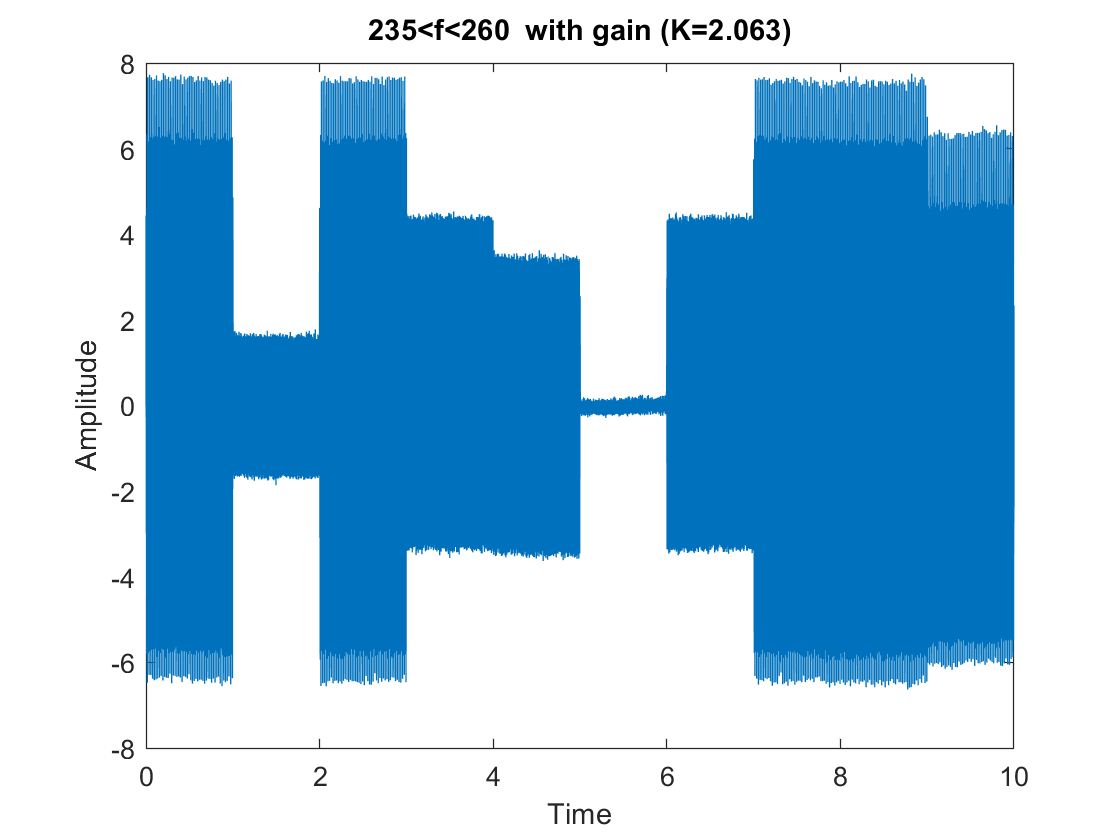

Y_NN = lsim(G, Y, t);

plot(t, Y_NN); 
xlabel('Time');
ylabel('Amplitude');
title('235<f<260 _ with gain (K=2.063)');

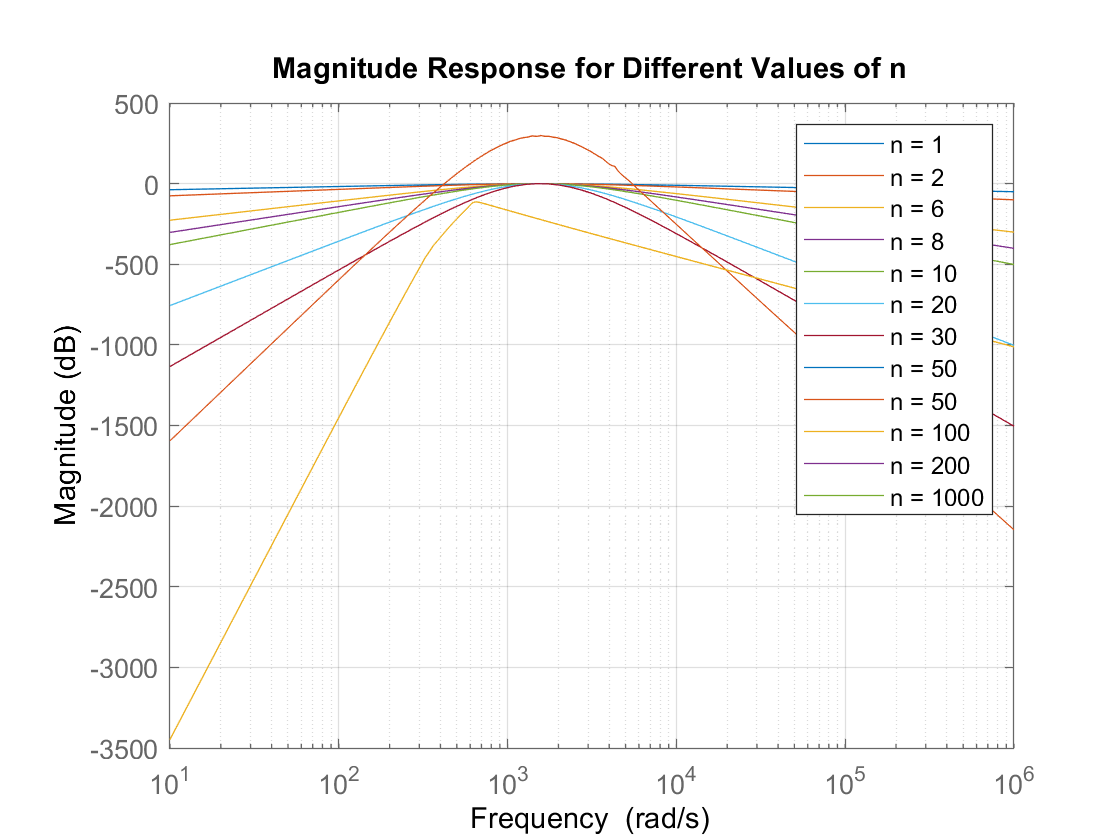

n = [1, 2, 6, 8, 10, 20, 30, 50, 50, 100, 200, 1000];
s = tf('s');
f1 = 240;
f2 = 255;
RC1 = 1 / (2 * pi * f1);
RC2 = 1 / (2 * pi * f2);

figure;
hold on;

legendCell = cell(1, numel(n)); 

for i = 1:numel(n)
    G = (2.063 * (RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1)))^n(i);
    bodemag(G);
    legendCell{i} = ['n = ' num2str(n(i))];
end

hold off;

legend(legendCell);
title('Magnitude Response for Different Values of n');
grid on;

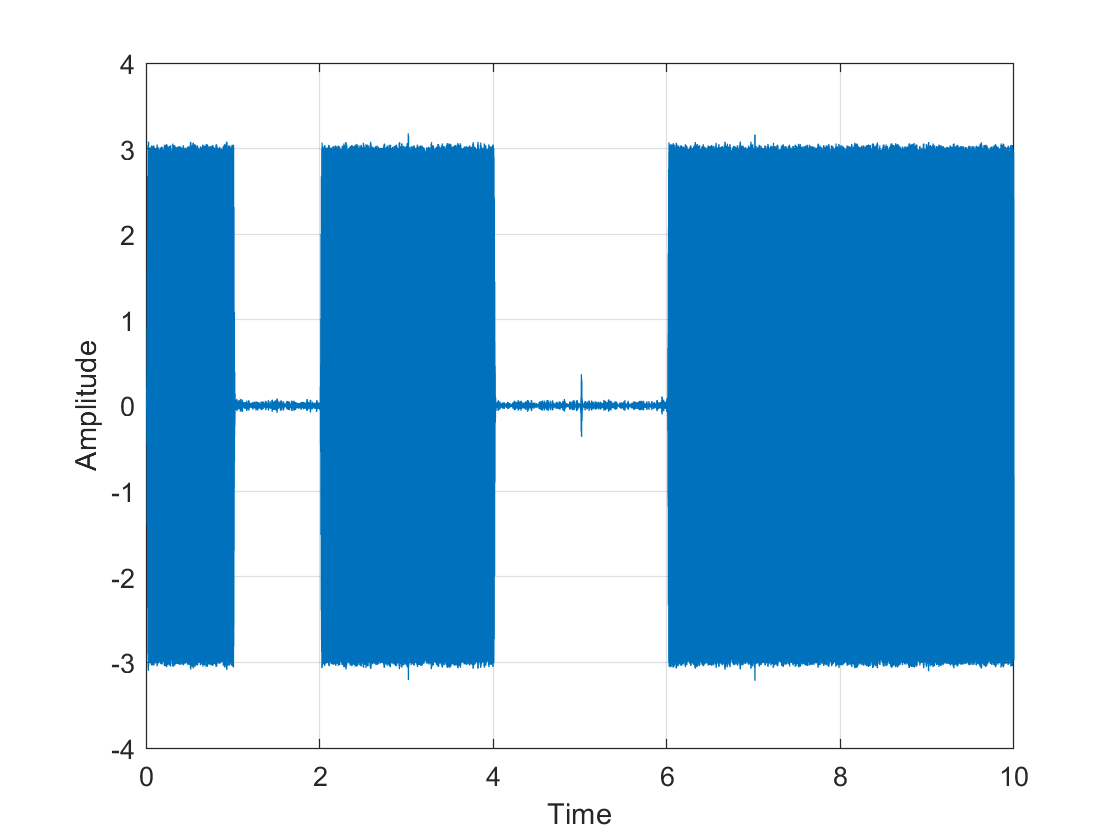

figure;
H_n = (2.063 * (RC2 * s) / ((RC1 * s + 1) * (RC2 * s + 1)))^25;
Y_n = lsim(H_n, Y, t);
plot(t, Y_n);
grid on;
xlabel('Time');
ylabel('Amplitude');